% Wavelet Demo
% William Ojemann
% April 24th, 2023

% Demonstration of how to use wavelet transforms to compare the frequency
% decomposition of one signal before and after a condition is changed (med
% taper). 
% 
% There is a toy signal I use here, but by changing the time
% vector, signal vector, and the breakpoint to your data (time, spike rate,
% and med taper time stamp) it should translate fairly well.

%clear; close all; clc

% add path of toolbox
addpath('/Volumes/users/nghosn3/tools/wavelet-coherence')

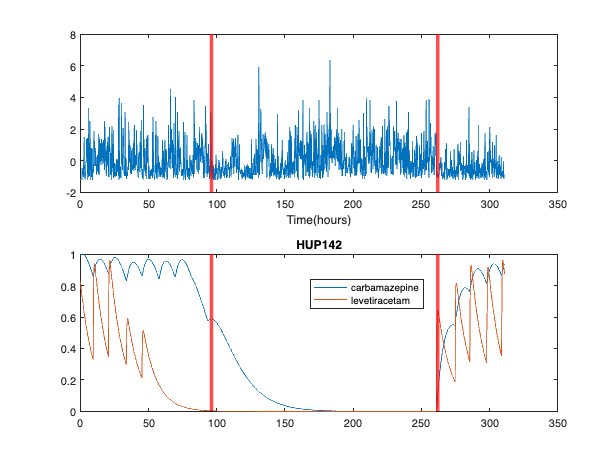

% Generating and Plotting Toy Signal

% These are the components you would change to your signal...
%%%%%%
% fs = 1e5; % Change
% time = linspace(0,1000,fs); % Change
% pre_cond_signal = sin(time) + 2*sin(time/5*pi*2) + sin(time/25*pi*2) + .5*sin(time/35*pi*2)+randn(1,length(time))*.5;
% breakpoint = find(time > 500,1);
% post_cond_signal = pre_cond_signal(breakpoint+1:end) - 1.5*sin(time(breakpoint+1:end)/5*pi*2)+1.5*sin(time(breakpoint+1:end)/15*pi*2);
% signal = zscore([pre_cond_signal(1:breakpoint),post_cond_signal]); % Change
%%%%%%

% test on HUP225
ipt=75;
fs = 6 ; % 6 sample every hour - units are in hours
exact_time = all_spike_times{ipt};
signal = zscore(all_spike_rate{ipt}); 
time =linspace(0,max(exact_time),length(signal))./3600;

% pre and post condition breakpoints
all_asm_inds = pt_data_clips.inds(ipt); all_asm_inds = all_asm_inds{:};
ind1 = max(all_asm_inds(:,2));
ind2 = min(all_asm_inds(:,3));

figure(1);clf; hold on
subplot(2,1,1)
plot(time,signal)
xline(time(ind1),'r-','linewidth',3); xline(time(ind2),'r-','linewidth',3)
xlabel('Time(hours)')
subplot(2,1,2)
plot(time, asm_load'); hold on;
xline(time(ind1),'r-','linewidth',3); xline(time(ind2),'r-','linewidth',3)
legend(med_names);title('HUP142')

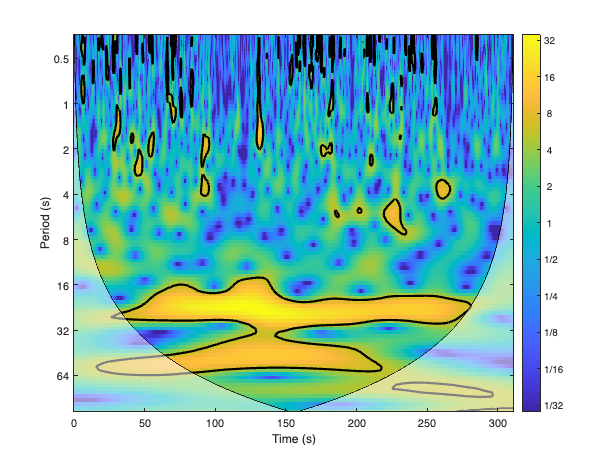

% Using the wavelet function from Torrence and Compo just to plot the
% spectrogram of the data
% black outline of spectrogram points denotes significance of peaks against
% red noise null model
figure(2);clf
wt([time',signal'],hours(1/fs))
ylabel('Period (s)')
xlabel('Time (s)')

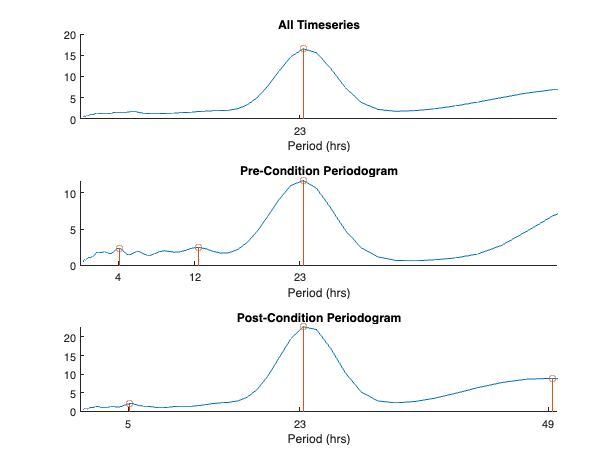


% Plotting periodograms at either side of condition point
% Calculate periodogram and wave
[wave,period,scale,coi] = wt([time',signal'],hours(1/fs));

prom_thresh = 0.5;

% plotting
figure(3);clf;
tiledlayout(3,1)
% Plot periodogram across whole timeseries
nexttile; hold on
% Calculate wavelet energy
all_periodogram = mean(abs(wave).^2,2);
plot(period,all_periodogram);
xlabel('Period (hrs)')
title('All Timeseries')
% Find the peaks (filter noise out with prominence)
[pks,locs] = findpeaks(all_periodogram,"MinPeakProminence",prom_thresh);
% if using different signal, will have to tune this prominence val
stem(period(locs),pks)
xticks(round(period(locs)))
xlim([0,50])

% Plot periodogram in pre-condition
nexttile; hold on
pre_periodogram = mean(abs(wave(:,1:ind1)).^2,2);
plot(period,pre_periodogram);
xlabel('Period (hrs)')
title('Pre-Condition Periodogram')
[pks,pre_locs] = findpeaks(pre_periodogram,"MinPeakProminence",prom_thresh);
stem(period(pre_locs),pks)
xticks(round(period(pre_locs)))
xlim([0,50])

% Plot periodogram in post-condition
nexttile; hold on
post_periodogram = mean(abs(wave(:,ind1+1:ind2)).^2,2);
plot(period,post_periodogram);
xlabel('Period (hrs)')
title('Post-Condition Periodogram')
[pks,post_locs] = findpeaks(post_periodogram,"MinPeakProminence",prom_thresh);
stem(period(post_locs),pks)
xticks(round(period(post_locs)))
xlim([0,50])

**NOTE: **you can see all of the components of the toy signal in the All Timeseries periodogram

You can imagine that our 5 second period signal is our circadian period of interest and we're interested in seeing how the magnitude changes between the two conditions

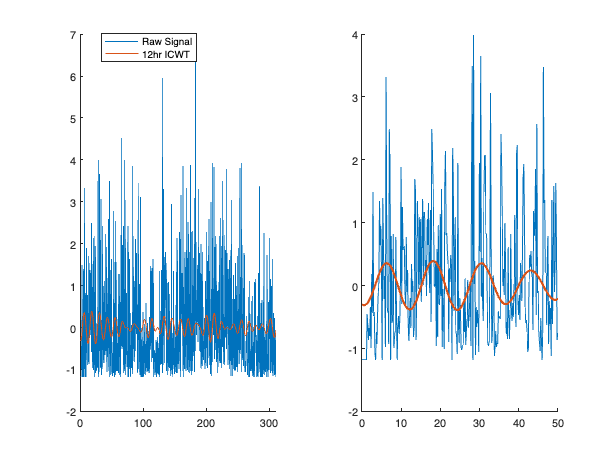

% Inverse Wavelet Transform
% Setting Constants from Torrence and Compo (TBL 2)
dt = 1/fs;
Cd = 0.776;
Psi0 = pi^(-.25);
dj = 1/12;
modifier = (dj*dt^(1/2))/(Cd*Psi0);

% Defining inverse wavelet function
invcwt = @ (wave,scale,pk_locs) modifier*sum(real(wave(pk_locs,:))./(scale(pk_locs)'.^(1/2)),1);

% Finding 5 sec peak period (with +/- 33% per Baud et. al., 2018)
pk_per = 12;
% You can also use the pre_pks found above by filtering for the specific peak of
% interest and instead of 5, pk_per = period(pk_loc) where pk_loc is the idx of peak of interest
err = 0.05; % bounds around frequency of interest
per_bounds = [pk_per-err*pk_per,pk_per+err*pk_per];
per_mask = period > per_bounds(1) & period < per_bounds(2);

% Plotting inverse wavelet and signal (scales changed for comparison)
inverse_wavelet = invcwt(wave,scale,per_mask);
figure(4);clf;
tiledlayout(1,2); nexttile; hold on
plot(time,signal,'LineWidth',.5)
plot(time,inverse_wavelet*5,'LineWidth',1,'LineStyle','-')
legend({"Raw Signal","12hr ICWT"})
nexttile; hold on
plot(time,signal,'LineWidth',.5)
plot(time,inverse_wavelet*5,'LineWidth',2,'LineStyle','-')
xlim([0,100])

Clearly it changes a lot...

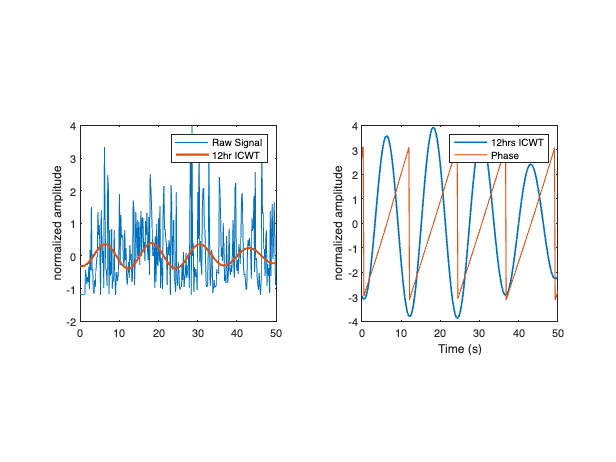

% Calculating inverse wavelet phase
invw_phase = angle(hilbert(inverse_wavelet));
figure(5);clf;
tiledlayout(1,2);nexttile;
plot(time,signal,'LineWidth',.5);hold on;
plot(time,inverse_wavelet*5,'LineWidth',2,'LineStyle','-')
xlim([0,50]);
axis square
ylabel('normalized amplitude')
legend({"Raw Signal","12hr ICWT"})
hold on
nexttile;
plot(time,inverse_wavelet*50,'LineWidth',1.5,'LineStyle','-');hold on;
plot(time,invw_phase,'LineWidth',1)
axis square
legend(["12hrs ICWT","Phase"])
xlim([0 50])
xlabel('Time (s)')
ylabel('normalized amplitude')

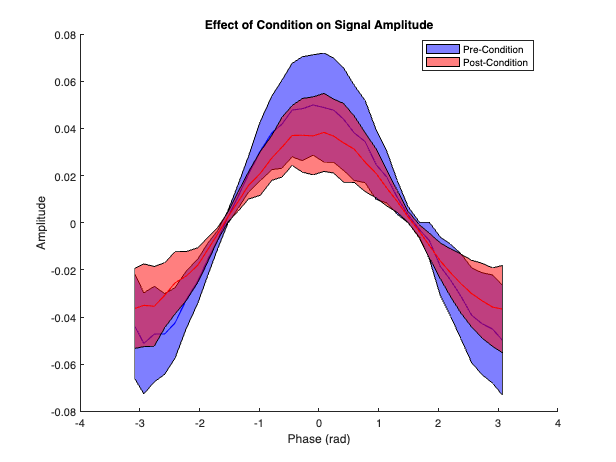

% Calculating Signal Difference between conditions

% condition masks
pre_mask = time <= time(ind1); post_mask = time > time(ind1) & time < time(ind2);

% breaking up phase into histograms
[~,~,idxs] = histcounts(invw_phase,36);
% Calculating x axis for plotting "folded" wavelets
period_bins = splitapply(@(x) mean(x),invw_phase(pre_mask),findgroups(idxs(pre_mask)));

% Calculating the average and std of signal in each phase bin within conditions
pre_bin_means = splitapply(@(x) mean(x),inverse_wavelet(pre_mask),findgroups(idxs(pre_mask)));
pre_bin_stds = splitapply(@(x) std(x),inverse_wavelet(pre_mask),findgroups(idxs(pre_mask)));

post_bin_means = splitapply(@(x) mean(x),inverse_wavelet(post_mask),findgroups(idxs(post_mask)));
post_bin_stds = splitapply(@(x) std(x),inverse_wavelet(post_mask),findgroups(idxs(post_mask)));

% Plotting
figure(6); clf; hold on;
plot(period_bins, pre_bin_means,'LineWidth',1,'Color','blue','HandleVisibility','off');
upper_bound = pre_bin_means + pre_bin_stds;
lower_bound = pre_bin_means - pre_bin_stds;
period_bins_flip = [period_bins,fliplr(period_bins)];
fill_between = [upper_bound,fliplr(lower_bound)];
fill(period_bins_flip,fill_between,'b','FaceAlpha',.5,'DisplayName',"Pre-Condition");

plot(period_bins, post_bin_means, 'LineWidth',1,'Color','red','HandleVisibility','off');
upper_bound = post_bin_means + post_bin_stds;
lower_bound = post_bin_means - post_bin_stds;
period_bins_flip = [period_bins,fliplr(period_bins)];
fill_between = [upper_bound,fliplr(lower_bound)];
fill(period_bins_flip,fill_between,'r','FaceAlpha',.5,"DisplayName","Post-Condition");
xlabel('Phase (rad)')
title('Effect of Condition on Signal Amplitude')
ylabel('Amplitude');
legend("Location","best")

With this code and the resulting wavelet power comparison you should be able to see the difference in signal power between two different conditions.

A ttest comparing the two distribution of peaks would reveal that there is (at least in the case of the toy signal) a statistically significant decrease in power after the condition is applied.